## Señal modulada ASK

La señal por desplazamiento de amplitud tambien es conocida por cierre y apertura, consiste en activar y desacivar una señal portadora senoidal con una señal binaria unipolar.

Es una modulacion binaria unipolar en una DSB-SC.

La señal ASK esta dada por S(t)


$$s\left(t\right)=A_{c\;} m\left(t\right)\;\cos \;\omega_c t$$


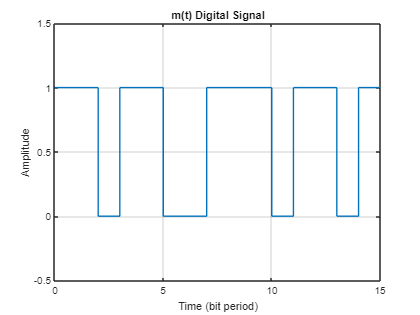

% The number of bits to send - Frame Length
N               =                 15;
time0           =            0:1:1514;
% Sampling rate - This will define the resoultion
fs              =             100;

% Generate a random bit stream
bit_stream      =   round(rand(1,N));


% Enter the two Amplitudes
% Amplitude for 0 bit
A1              =                  0; 
% Amplitude for 1 bit Ac in the diagram is the A2 in the code
A2              =                  5; % esta es la amplitud total, por lo cual sera de -2.5v a 2.5v
% Frequency of Modulating Signal
f               =                  1;

% Time for one bit 
% Cual es el tiempo de Signo 0.01 seg 
t               = 0: 1/fs : 1;
% This time variable is just for plot
time            = [];
ASK_signal      = [];
Digital_signal  = [];
% Frecuency of Carry Signal es 100 Hz
carry_signal    = cos(2*pi*f*t);

% Ciclo para rellenar la señal ASK acorde al tamaño del bit stream
for ii = 1: 1: length(bit_stream)
    
    % The ASK Signal
    ASK_signal = [ASK_signal (bit_stream(ii)==0)*A1/2*carry_signal+...
        (bit_stream(ii)==1)*A2/2*carry_signal];
    
    % The Original Digital Signal
    Digital_signal = [Digital_signal (bit_stream(ii)==0)*...
        zeros(1,length(t)) + (bit_stream(ii)==1)*ones(1,length(t))];
    
    time = [time t];
    t =  t + 1;
   
end

%sorry for the incoveniente but time was define in the for loop
%freq axix
time_res     = 100/(length(time)-1);
freq0        =  -fs/2:time_res:fs/2;

% Plot the m(t) Digital Signal
plot(time,Digital_signal);
xlabel('Time (bit period)');
ylabel('Amplitude');
title('m(t) Digital Signal');
axis([0 time(end) -0.5 1.5]);
grid on;

La señal ASK tendra un rango de valores de -2.5V a 2.5V

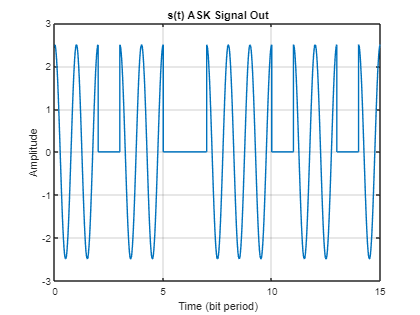


% Plot the ASK Signal
plot(time,ASK_signal);
xlabel('Time (bit period)');
ylabel('Amplitude');
title('s(t) ASK Signal Out');
axis([0 time(end) -3 3]);
grid  on;

## Demodulacion ASK por envolvente

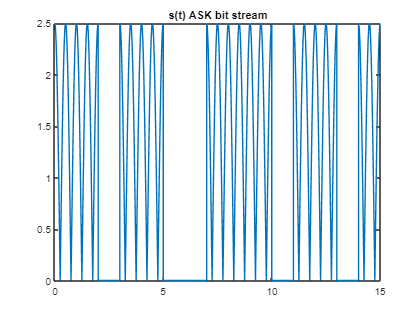

% Sacar el Valor Absoluto de l señal modulada
ask_signal_in   =   abs (ASK_signal);
plot(time,ask_signal_in);
title('s(t) ASK bit stream');

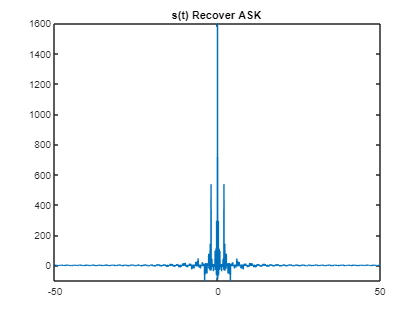


% convertir a frecuencia
ask_signal_freq     =   real(ttof(ask_signal_in));
plot(freq0,ask_signal_freq);
title('s(t) Recover ASK ');
% Tiempos en espectro señal ASK recuperada
xlim([-fs/2 fs/2])
ylim([-100 1600])

% para recortar la señal y solo agarrar DBLSC
time_filter = 0:1:300;
time_recover_signal = 0:1:1814;

% FILTRO RECORTADOR
filtro2 = rcosine(1,50);

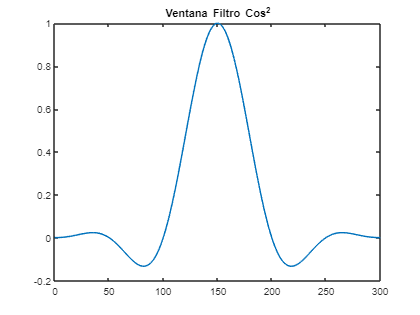

%VENTANA FILTRO
plot(time_filter, filtro2);
title('Ventana Filtro Cos^2');

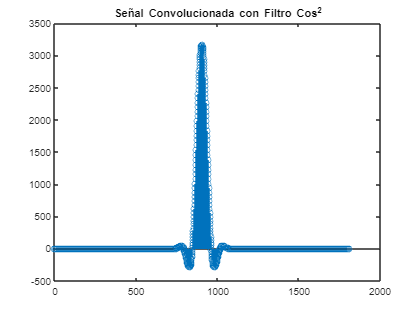


% CONVOLUTION WITH THE WINDOW
res = conv(ask_signal_freq,filtro2);
stem(time_recover_signal, res);
title('Señal Convolucionada con Filtro Cos^2');

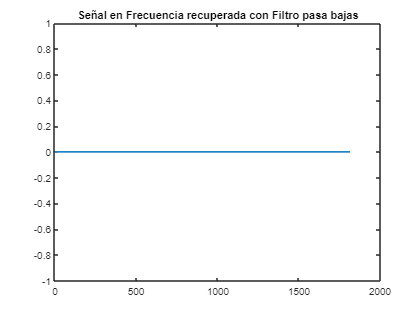


%Filtro pasabajas
freq =  0:1:1814;
%establecer el filtro en 0
lowpassFilter = zeros(1,length(freq));
%make 1 the range of values that wanna be filtered
%lowpassFilter = 

Demodule_ask = lowpassFilter.*res; % applying filter

% PASS from the FRECUENCY TO  TIME
Demodule_ask = real(ftot(Demodule_ask)); % convert to time
plot(time_recover_signal,Demodule_ask);
title('Señal en Frecuencia recuperada con Filtro pasa bajas');